%function [Knuckle,Strut] = Lotus_AARM(z,ChassiHP,KnuckleHP,StrutIn)

%Chassi HPs include the points in order [[upper forward];[upper
%rear];[lower forward];[lower rear]]

%Knuckle HPs include points in order [[upper Knuckle point];[Lower knuckle
%Point]];

%Strut Points are [[Upper mounting point];[lower mounting point]];

%TieRod points are [[Rack end]; [Knuckle end]];

HP=readtable("HardPoints.xlsx");

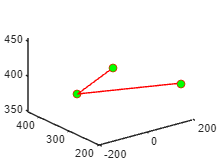

zin = 15;
% HP=table2array(HP);
ChassiHP = [[HP{1,2} HP{1,3} (HP{1,4})]; [HP{2,2} HP{2,3} (HP{2,4})]; [HP{3,2} HP{3,3} HP{3,4}]; [HP{4,2} HP{4,3} HP{4,4}]];
StrutIn = [[HP{11,2} HP{11,3} HP{11,4}]; [HP{12,2} HP{12,3} HP{12,4}]];
KnuckleHP = [[HP{7,2} HP{7,3} HP{7,4}]; [HP{8,2} HP{8,3} HP{8,4}]];
TieRodIn = [[HP{16,2} HP{16,3} HP{16,4}];[HP{15,2} HP{15,3} HP{15,4}]];

Axis_s = string(HP{20,1});
Side_s = string(HP{22,1});

Plot_Suspension(ChassiHP,KnuckleHP,StrutIn,TieRodIn,'Un-Rotated','blue')

### **Aligned with -Y to Forward  axis, -X as Right Axis and +Z as Up axis**

This is due to the code configuration.

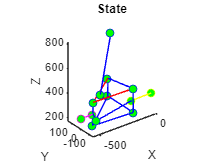

[Rotation,FLIP]=Rotation_FLIP(Axis_s, Side_s);

ChassiHP=RZ(ChassiHP,Rotation,FLIP);
StrutIn=RZ(StrutIn,Rotation,FLIP);
KnuckleHP=RZ(KnuckleHP,Rotation,FLIP);
TieRodIn=RZ(TieRodIn,Rotation,FLIP);
WheelSpindle=RZ([0.00 450.00 266.70],180,FLIP); %EDIT

Plot_Suspension(ChassiHP,KnuckleHP,StrutIn,TieRodIn,'State','blue',[(KnuckleHP(1,:)+KnuckleHP(2,:))/2;((KnuckleHP(1,:)+KnuckleHP(2,:))/2 + [-100 0 0])])

%Natural State
[c,t,cs,kp,sl,laa]=OP_Param(ChassiHP,StrutIn,KnuckleHP,TieRodIn,0,-52.9)

Unrecognized function or variable 'ChassiHP'.

Plot_Suspension(ChassiHP,Knuckle,Strut,TieRod,'Natural State','blue',[(KnuckleHP(1,:)+KnuckleHP(2,:))/2;((KnuckleHP(1,:)+KnuckleHP(2,:))/2 + [-100 0 0])])



z=-127:50:168;

Camber=zeros(length(z),1);
Toe=Camber;
Castor=Camber;
Kingpin=Camber;
StrutLength=Camber;
MotionRatio=Camber;
LowerArmAngle=Camber;
delx=0;

for i=1:length(z)
   [c,t,cs,kp,sl,laa] = OP_Param(ChassiHP,StrutIn,KnuckleHP,TieRodIn,z(i),delx);
   Camber(i)=c;
   Toe(i)=t;
   Castor(i)=cs;
   Kingpin(i)=kp;
   StrutLength(i)=sl;
   LowerArmAngle(i)=laa;
end

del = -55:1:55;
Toe_Change=zeros(length(del),1);

for i=1:length(del)
   [~,t,~,~,~,~] = OP_Param(ChassiHP,StrutIn,KnuckleHP,TieRodIn,0,del(i));
   Toe_Change(i)=t;
end

MotionRatio(1)=abs((StrutLength(2)-StrutLength(1))/(z(2)-z(1)));
for i=2:(length(z)-1)
    MotionRatio(i)=abs((StrutLength(i+1)-StrutLength(i-1))/(z(i+1)-z(i-1)));
end
MotionRatio(end)=abs((StrutLength(end)-StrutLength(end-1))/(z(end)-z(end-1)));


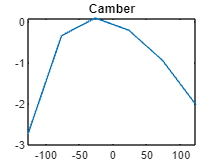


plot(z,Camber)
title('Camber')

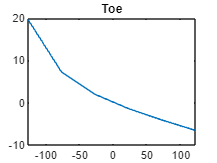


plot(z,Toe)
title('Toe')

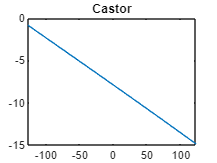


plot(z,Castor)
title('Castor')

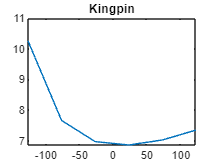


plot(z,Kingpin)
title('Kingpin')

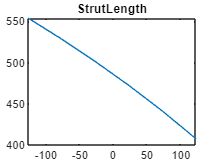


plot(z,StrutLength)
title('StrutLength')

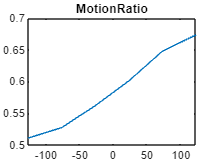


plot(z,MotionRatio)
title('MotionRatio')

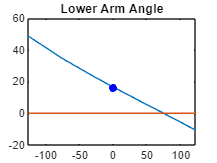


plot(z,LowerArmAngle)
hold on
plot(z,z*0)
scatter(0,interp1(z,LowerArmAngle,0),'ob','filled');
plot(0,interp1(z,LowerArmAngle,0))
hold off
title('Lower Arm Angle')

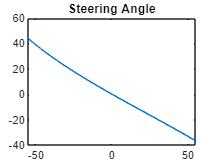


plot(del, Toe_Change)
title('Steering Angle')

LowerArmAngle_MAX=max(LowerArmAngle)
LowerArmAngle_MIN=min(LowerArmAngle)
LowerArmAngle_BASESTATE=interp1(z,LowerArmAngle,0)


MotionRatio_Mean=-1*mean(MotionRatio)

% [Minimum, At zero Vertical Displacement, Maximum]
% [camber,Toe,Castor,KingPIN,StrutLEN,LowerArmAngle,MotionRatioo] = Front_Susp_Parameters(ChassiHP,StrutIn,KnuckleHP,TieRodIn,z,0)

% 
% Main Code to Calculate Performance
